# Finding Parameters

## Finding Natural Frequency

% angles taken from the serial moniter when Rocky was swung back and forth
angles = [1.65
1.64
1.63
1.62
1.61
1.66
1.66
1.68
1.71
1.75
1.81
1.86
1.93
2.02
2.11
2.22
2.32
2.44
2.56
2.65
2.74
2.82
2.87
2.90
-1.66
-1.66
-1.69
-1.73
-1.79
-1.86
-1.93
-2.02
-2.10
-2.16
-2.24
-2.31
-2.35
-2.39
1.66
1.66
1.69
1.72
1.78
1.85
1.92
2.00
2.08
2.14
2.21
2.26
2.28
2.29
-1.66
-1.68
-1.71
-1.76
-1.82
-1.90
-1.95
-2.03
-2.10
-2.15
-2.21
-2.24
-2.26
1.66
1.67
1.70
1.75
1.81
1.88
1.95
2.01
2.09
2.15
2.19
2.23
-1.66
-1.66
-1.67
-1.70
-1.74
-1.80
-1.85
-1.92
-1.99
-2.04
-2.11
-2.16
-2.19
-2.21
1.66
1.66
1.69
1.72
1.78
1.84
1.90
1.97
2.04
2.09
2.15
2.18
2.20
-1.66
-1.67
-1.69
-1.73
-1.77
-1.83
-1.90
-1.95
-2.01
-2.08
-2.12
-2.16
-2.18
1.66
1.66
1.68
1.71
1.76
1.81
1.87
1.94
1.99
2.05
2.09
2.13
2.16
2.17
-1.66
-1.68
-1.70
-1.75
-1.80
-1.85
-1.91
-1.98
-2.02
-2.07
-2.10
-2.13
-2.15
1.66
1.67
1.70
1.74
1.79
1.84
1.89
1.95
2.00
2.05
2.09
2.11
2.13
-1.66
-1.67
-1.69
-1.73
-1.77
-1.82
-1.88
-1.93
];

% making it so the spacing between points is 1/20th of the second
total = 165;
t = linspace(0,0.05*(total - 1),total);

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


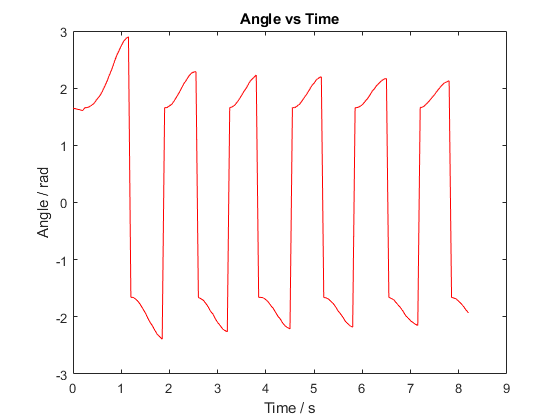

% plotting time vs angle
plot(t,angles,'r')
xlabel('Time / s')
ylabel('Angle / rad')
title('Angle vs Time')

% period is about 1, nf is 2pi/period
period = 3.8 -2.55;
%finding natural frequency
natural_freq = 2*pi/(period)

natural_freq = 5.0265

g = 9.8;
l = g/(natural_freq^2)

l = 0.3879

%converting l in meters to inches: 0.3879 m = 15.27 inches

## Finding Motor Parameters

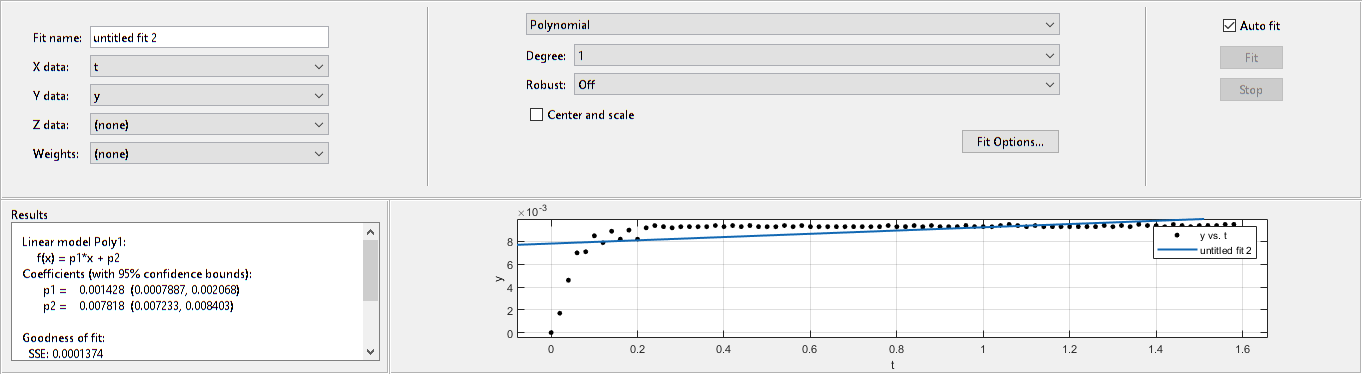

% data for the left and right wheel speeds taken from the serial moniter of
% the arduino
left_R =[0.00,0.00;
0.17,0.15;
0.45,0.45;
0.68,0.68;
0.71,0.71;
0.84,0.84;
0.80,0.79;
0.88,0.89;
0.82,0.82;
0.90,0.92;
0.84,0.85;
0.92,0.92;
0.94,0.92;
0.93,0.93;
0.94,0.93;
0.93,0.94;
0.94,0.93;
0.94,0.93;
0.94,0.93;
0.93,0.92;
0.93,0.93;
0.93,0.93;
0.94,0.94;
0.94,0.94;
0.94,0.94;
0.94,0.94;
0.93,0.93;
0.93,0.94;
0.94,0.94;
0.93,0.94;
0.94,0.94;
0.95,0.93;
0.93,0.93;
0.94,0.93;
0.95,0.93;
0.94,0.93;
0.94,0.94;
0.94,0.94;
0.93,0.92;
0.93,0.93;
0.93,0.94;
0.94,0.94;
0.93,0.94;
0.93,0.93;
0.94,0.94;
0.95,0.93;
0.94,0.93;
0.93,0.92;
0.93,0.93;
0.93,0.93;
0.93,0.93;
0.93,0.93;
0.93,0.93;
0.93,0.93;
0.93,0.93;
0.94,0.93;
0.93,0.93;
0.94,0.94;
0.93,0.93;
0.93,0.92;
0.94,0.92;
0.93,0.92;
0.93,0.93;
0.94,0.94;
0.93,0.94;
0.94,0.93;
0.93,0.94;
0.93,0.94;
0.94,0.94;
0.94,0.93;
0.94,0.94;
0.94,0.94;
0.94,0.93;
0.94,0.93;
0.94,0.92;
0.94,0.93;
0.93,0.92;
0.93,0.93;
0.94,0.93;
0.93,0.93];

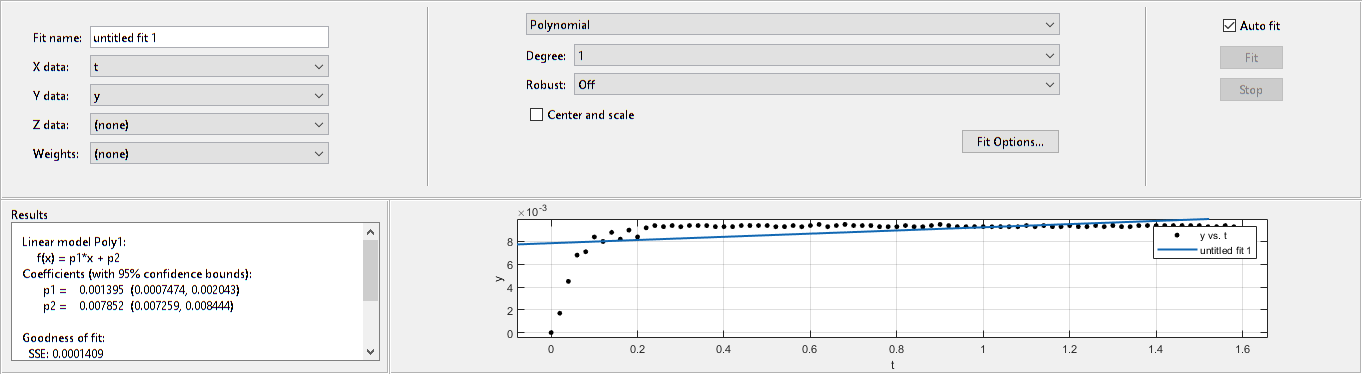

total = 80;
% divide by 100 to make speed in m/s
wheel_speeds = left_R./100;
% create a time variable in seconds
t = linspace(0,0.02*(total - 1),total);
% curve fitting
cftool(t,wheel_speeds(:,1))

The values from the cftool that we got for a and b are 17.84 and 0.009341.